# Lecture 7

## Power Spectrum Estimation

### Spectral Leakage

Leakage is an artefact of an FFT applied to a non-periodic data. Even if a signal is periodic like a sinousoid, when the signal is measured with some interval it can be non-periodic. The issue is that FFT  assumes that the signal is periodic and repeats itself after the measured interval. This is not the case when the data is non-periodic, which contains sharp transitions at the end of each measured interval. These sharp changes have a broad frequency response which lead to spectral leakage. Windows can help ***minimize*** the effects of leakage by smoothing the time domain signal, but cannot eliminate leakage.

A signal with leakage (green in *Figure 2*) has lower amplitude and a broader frequency response than a signal with no leakage (red in *Figure 2*). This makes it difficult to quantify the signal properly in the frequency domain.

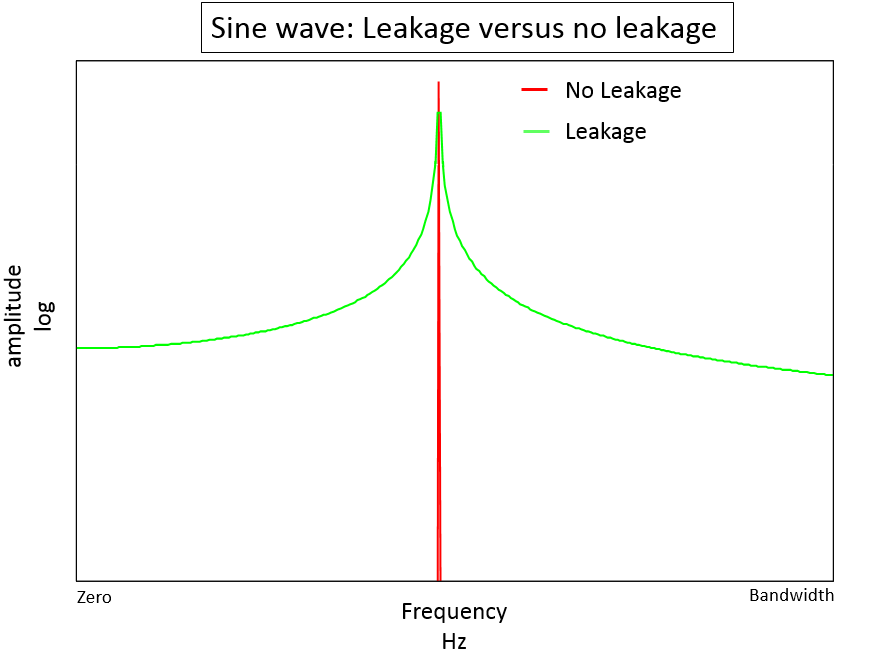

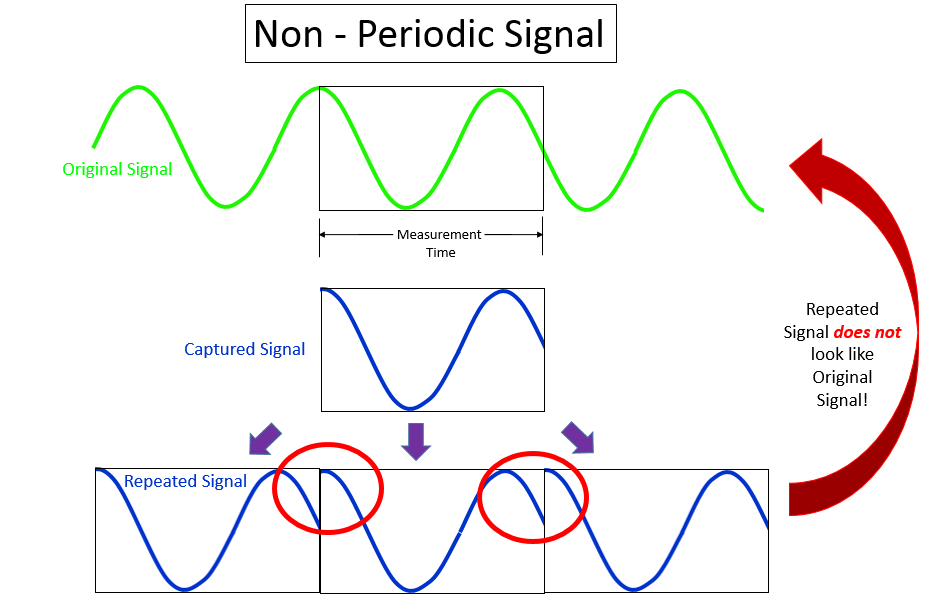

To reduce leakage, a mathematical function called a window is applied to the data. Windows are designed to reduce the sharp transient in the re-created signal as much as possible.

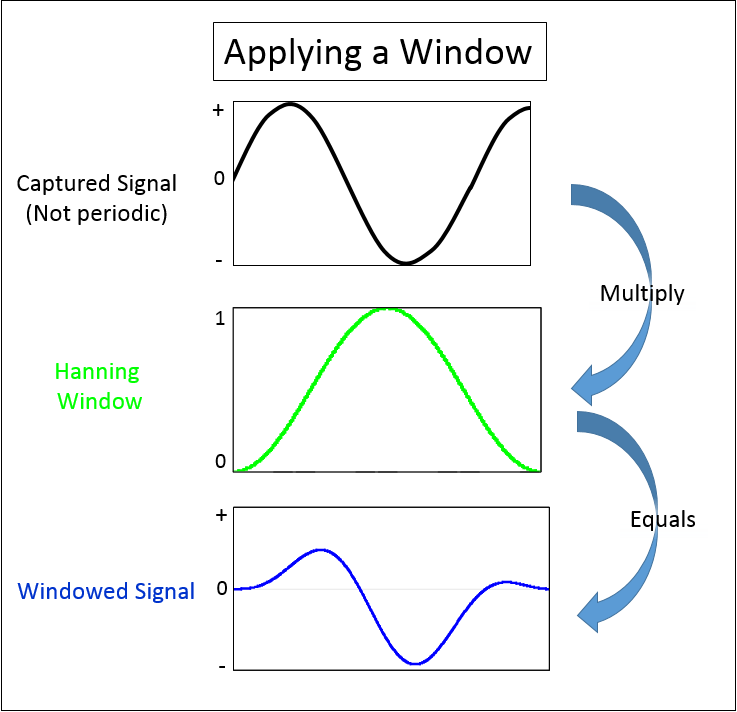

The main benefit of windowing is that the leakage is now confined over a smaller frequency range, instead of affecting the entire frequency bandwidth of the measurement.

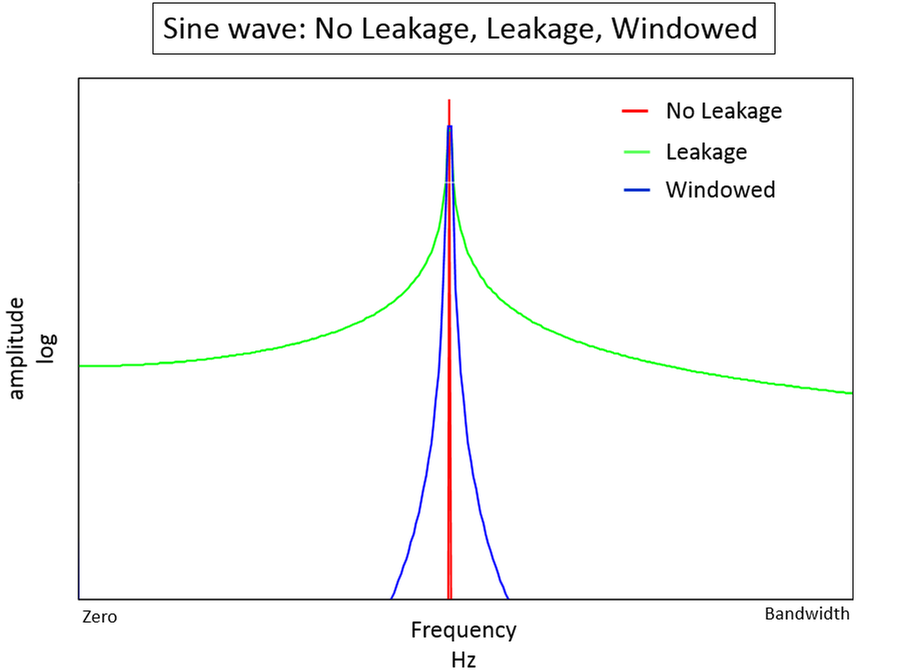

### Modified Periodogram

The modified periodogram uses a window $w\left(n\right)$ that is not rectangular.

        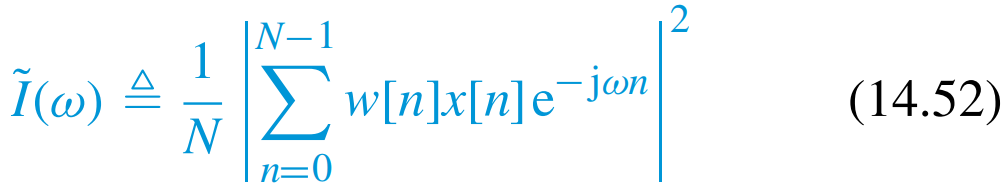

The normailisation factor has to be

        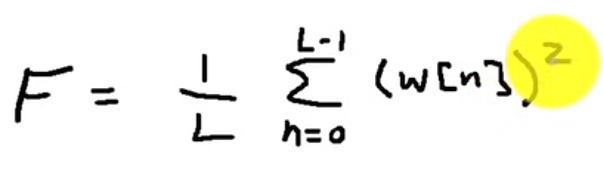

### Bartlett Window

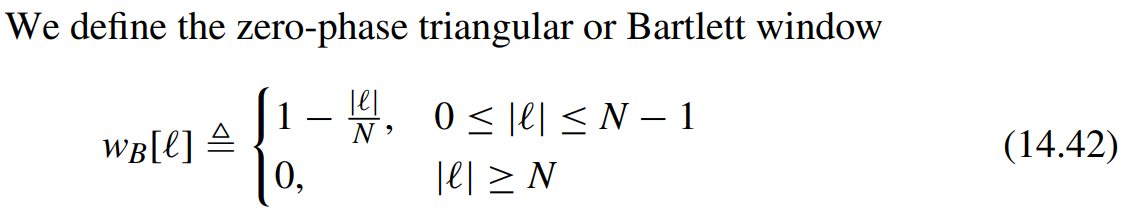

w = bartlett(64);
plot(w)
F = fft(w);
plot(abs(fft(w)))

## Welch's method

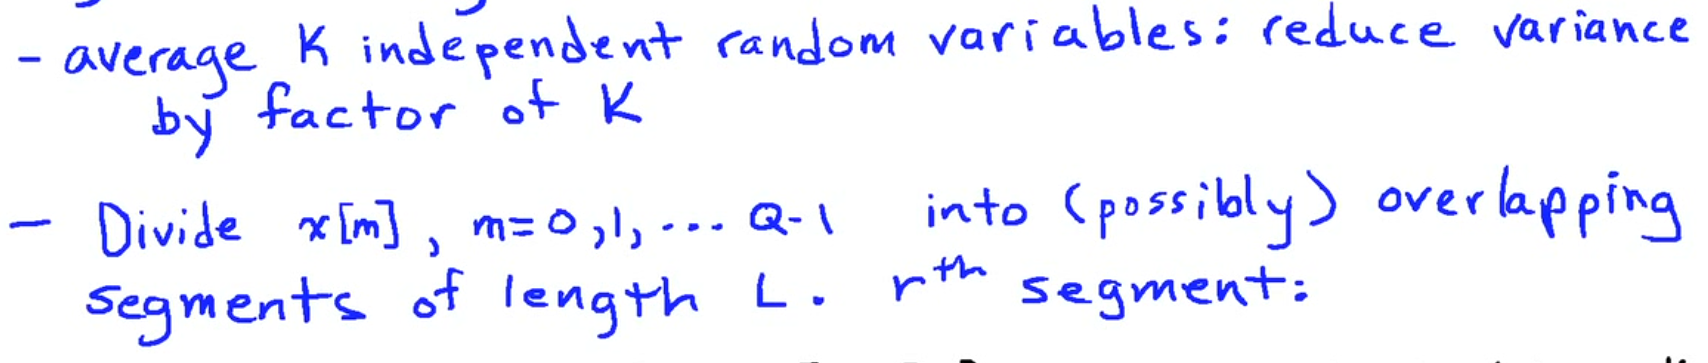

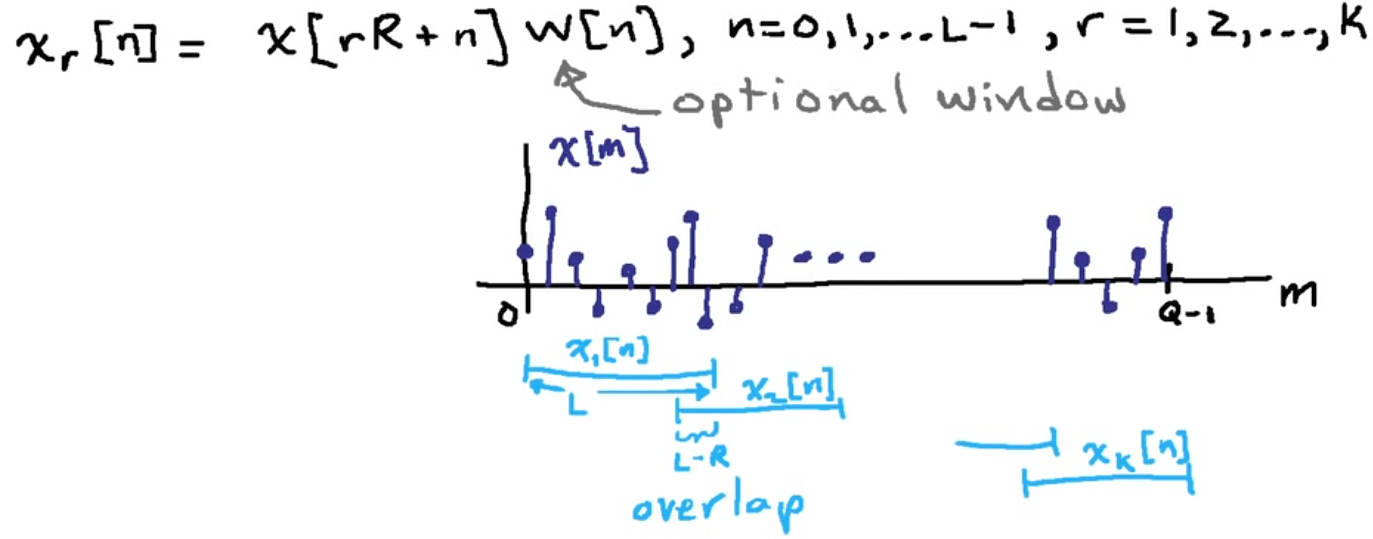 

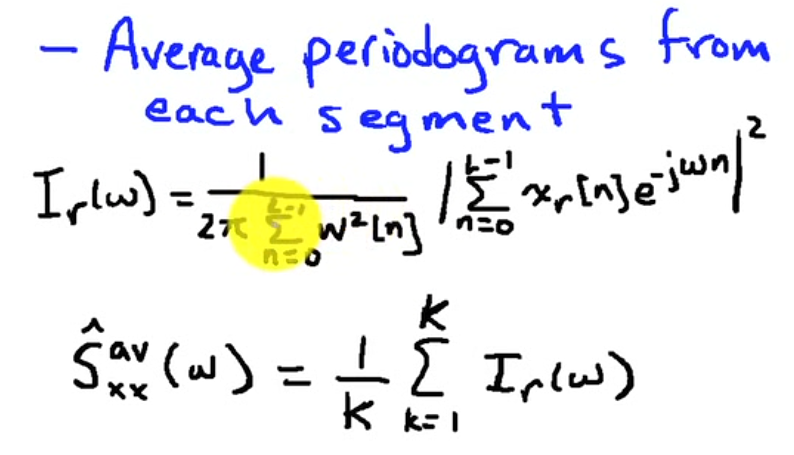

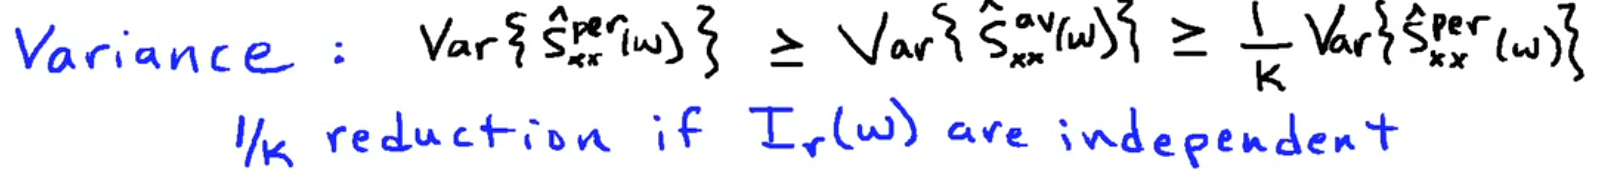

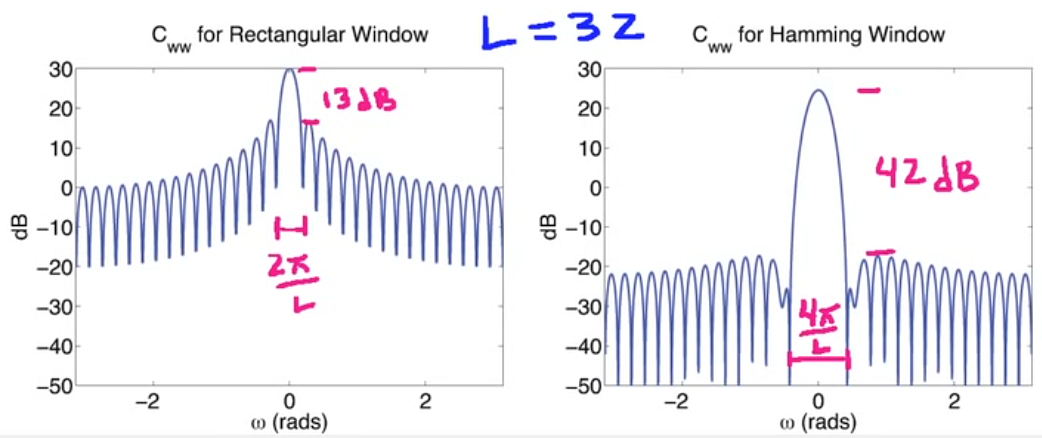

The nature of bias depends on the chosen window. There is a trade-off between main lobe width and side-lobe height. 

- Rectangular window gives you the narrowest main lobe but a fairly large side-lobe height. 

- Hamming window gives you twice the main lobe width but the side-lobes are much lower.

Hamming window sacrifies some resolution for increased dynamic range.

Dynamic range is the ratio of the largest signal amplitute and the smallest signal amplitude. How well can we realible distintinguish the largest from the smallest.

Windows are used to manage bias. 

Typically, we will trade resolution (main-lobe width) for dynamic range (side-lobe height)

## Functions

function r=acrs(x, L)
    % Computes the ACRS r[m] for 0<= m <= L
    % r=acrs(x-mean(x),L) yields the ACVS
    N=length(x);
    x1=zeros(N+L-1,1);
    x2=x1;
    x1(1:N,1)=x;
    for m=1:L
        x2=zeros(N+L-1,1);
        x2(m:N+m-1,1)=x;
        r(m)=x1'*x2;
    end
    r=r(:)/N;
end

function I=psdper(x, K)
    % Compute periodogram I(ω) using the FFT.
    % K-point FFT >= N
    N=length(x);
    X=fft(x,K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function r=acrsfft(x, L)
    % Computate the autocorrelation sequence using the FFT.
    % r=acrsfft(x-mean(x),L) yields the ACVS
    N=length(x);
    Q=nextpow2(N+L);
    X=fft(x,2^Q);
    r0=real(ifft(X.*conj(X)));
    r=r0(1:L)/N;
end

function I=psdmodper(x, K)
    % Compute the modified periodogram PSD estimate.
    % K-point FFT >= N
    N=length(x);
    w=hann(N); % choose window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    X=fft(x(:).*w(:),K);
    I=X.*conj(X)/N;
    I(1)=I(2); % Avoid DC bias
    I=I(:);
end

function psdbt(x, L, K)
    % Computate the Blackman–Tukey PSD estimate.
    % Blackman–Tukey PSD estimator of S(2*pi*k/K)
    N=length(x);
    w=hann(N); % Data window
    w=w/(norm(w)/sqrt(N)); % sum wˆ2[k]=N
    x=x.*w; % Data windowing
    r=acrsfft(x,L);
    wc=parzenwin(2*L-1); % Lag window
    rw=r.*wc(L:2*L-1); % Lag windowing
    g=zeros(K,1);
    g(1:L)=rw;
    g(K-L+2:K)=flipud(rw(2:L));
    G=fft(g,K); % f even => F real
    S=2*real(G(1:K/2)); S(1)=S(2);
end

function S=psdwelch(x, L, K)
    % Compute the Welch PSD estimate.
    % Welch PSD estimator of S(2*pi*k/K)
    M=fix((length(x)-L/2)/(L/2)) % 50% overlap
    time=(1:L)';
    I=zeros(K,1);
    w=hanning(L); % Choose window
    w=w/(norm(w)/sqrt(L)); % sum wˆ2[k]=L
    for m=1:M
    %xw=w.*detrend(x(time)); % detrenting
    xw=w.*x(time); % data windowing
    X=fft(xw,K);
    I=I+X.*conj(X);
    time=time+L/2;
    end
    I=I/(M*L); S=2*I(1:K/2); S(1)=S(2);
end